# Sprawozadanie

# z Laboratorium Metod numerycznych

## Ćwiczenie 1:

## Błędy w obliczeniach numerycznych

Autor: Imię Nazwisko NR_INDEKSU

Data wykonania ćwiczenia: 

Data sporządzenia i oddania sprawozdania:

**Uwaga!**: *Przed utworzeniem pliku PDF, który ma zostać przesłany na platformę WIKAMP jako sprawozdanie, pozamieniaj tekst w trybie rozkazującym na tryb oznajmujący i usuń fragmenty tekstu które nie będą miały sensu po stworzeniu działającego kodu. *

### Część 1. Obliczanie wielomianu różnymi

Napisać funkcje obliczające wartość wielomianu jako ważonej sumy potęg zmiennej niezależnej (funkcja `pval1` i `pval2` na końcu sprawozdania) oraz przy pomocy schematu Hornera (funkcja `horner`). Dla wielomianu


$$W\left(x\right)={\left(x-x_0 \right)}^9$$


gdzie $x_0 =\frac{3}{2}$  przetestowano te funkcje dla argumentów pojedynczej i podwójnej precyzji.

format long
format compact

Pierwszy wariant funkcji obliczającej wartość wielomianu ma nosić nazwę `pval1` i dodawać  wyrazy wielomianu w porządku malejących potęg czyli $p_{1\;} x^n +p_2 x^{n-1} +\ldots+p_n x+p_{n+1}$ od lewej do prawej. Na początek tworzymy dane testowe w postaci współczynników wielomianu stopnia 3


$$P(x)=(x+1)(x-2)(2 x-3)$$


oraz wektor wartości zmiennej niezależnej

p=[2,-5,-1,6]

p =      2    -5    -1     6


x=[-2,-1,0,1,2,3,4]

x =     -2    -1     0     1     2     3     4


### W dalszej części, ze względu na to, że analizator kodu Matlab-a w Live Editor sprawdza wszyskie sekcje, nawet przy zastosowaniu polecenia "Run Section", niektóre **niekompletne **linie kodu zostały "wykomentowane" - trzeba je uzupełnić lub zastąpić właściwym kodem i usunąc komentarz.

Uzupełnij poniższy kod i usuń znaki komentarza, które "ukrywają" obecnie nieprawidłowe syntaktycznie linie przed analizatorem kodu. Po sprawdzeniu kodu (przy użyciu "Run Section" skopiuj kod do nowej sekcji, zaznacz część między komentarzami z podwójną linią ze znaków równości i wybierz z menu kontekstowego "*Convert to local function*" i nazwij ją `pval1`

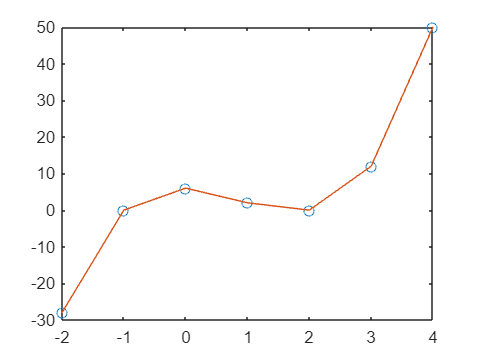

%=================================================================
y = pval1(p, x);
%=================================================================
plot(x,y,'o',x,polyval(p,x),'-')

Drugi wariant powinien dodawać wyrazy wielomianu w porządku rosnących potęg (po sprawdzeniu, podobnie jak poprzednio, skopiuj kod do nowej sekcji i przekształć kod na funkcję lokalną i nazwij `pval2`):

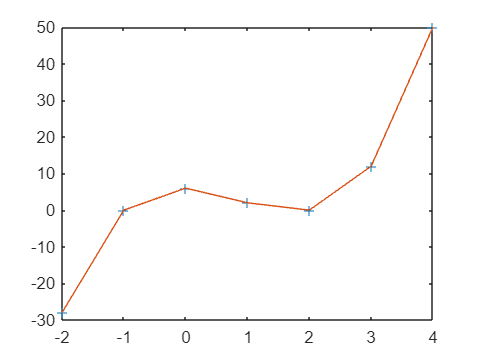

%==========================================================
y = pval2(p, x);
%==========================================================
plot(x,y,'+',x, polyval(p,x))

Wariant trzeci ma realizować schemat Hornera (nazwa `horner`), to znaczy według schematu po prawej stronie poniższego równania (zwróć uwagę, że zakres indeksów współczynników wielomianu jest dostosowany do indeksowania zmiennych w Matlab-ie, a *n* oznacza stopień wielomianu)


$$p_{1\;} x^n +p_2 x^{n-1} +\ldots+p_n x+p_{n+1} =\left(\left(\ldots\left(\left(p_1 x+p_2 \right)x+p_3 \right)x+\ldots\;\right)x+p_n \right)x+p_{n+1}$$


Wyrażenie ma być obliczane ściśle w porządku określonym przez nawiasy, więc trzeba zastosować pętlę w której zmiennej pomocniczej będą nadawane wartości kolejnych, coraz bardziej zewnętrznych nawiasów.

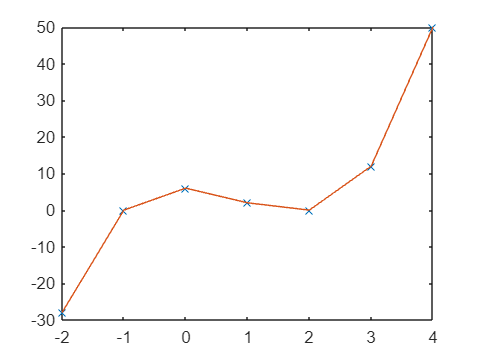

%=====================================================
y = horner(p, x);
%=====================================================
plot(x,y,'x',x,polyval(p,x),'-')

Obserwacja działania napisanych funkcji dla podanego na wstępie wielomianu posiadającego zero wielokrotne

w=3*ones(1,9)/2

w =    1.500000000000000   1.500000000000000   1.500000000000000   1.500000000000000   1.500000000000000   1.500000000000000   1.500000000000000   1.500000000000000   1.500000000000000


p=poly(w) % Wygenerowanie współczynników wielomianu 9 stopnia wspomnianego na wstępie

p = 1.0e+02 *

   0.010000000000000  -0.135000000000000   0.810000000000000  -2.835000000000000   6.378750000000000  -9.568125000000000   9.568125000000000  -6.150937500000000   2.306601562500000  -0.384433593750000


Narysowanie wykresów rozważanego wielomianu w przedziale [1.45, 1.55], zawsze we wspólnym układzie współrzędnych z tymże wielomianem obliczonym jako 9 potęga dwumianu

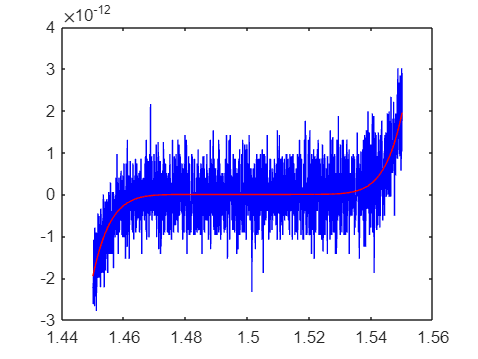

x=linspace(1.45,1.55,2049); % Wygenerowanie gęstej siatki punktów
y0=(x-3/2).^9; % Obliczenie wielomianu jako potęgi dwumianu (do porównań)
plot(x,pval1(p,x),'b-',x,y0,'r-')

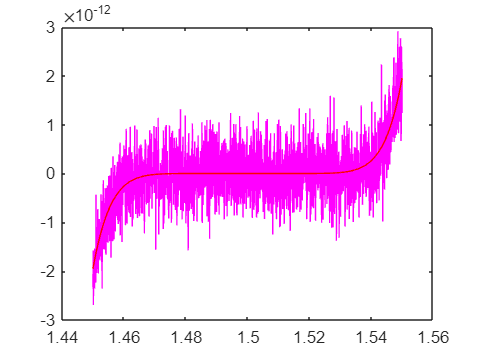

plot(x,pval2(p,x),'m-',x,y0,'r-')

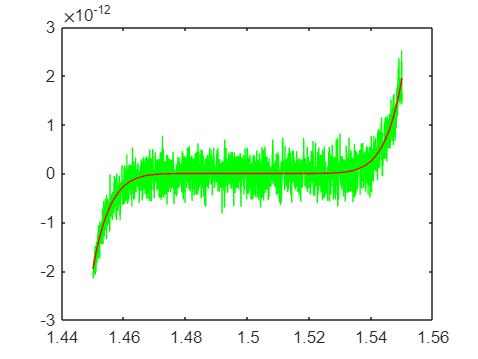

plot(x,horner(p,x),'g-',x,y0,'r-')

Porównaj w analogiczny sposób wyniki obliczeń wrzystkich trzech wariantów funkcji z wbudowaną funkcją Matlab'a `polyval`

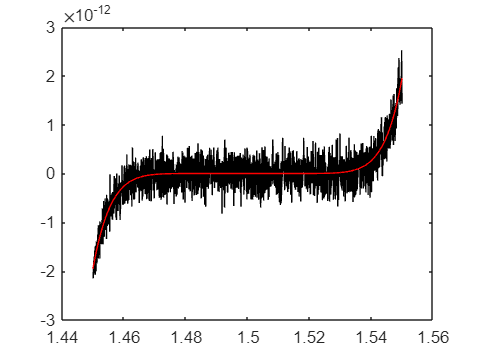

plot(x,polyval(p,x),'k-',x,y0,'r-')


err_pval1 = sqrt(mean((pval1(p,x)-y0).^2))

err_pval1 =      5.912429915366391e-13

err_pval2 = sqrt(mean((pval2(p,x)-y0).^2))

err_pval2 =      4.792622125230379e-13

err_horner = sqrt(mean((horner(p,x)-y0).^2))

err_horner =      2.601181922156722e-13

err_polyval = sqrt(mean((polyval(p,x)-y0).^2))

err_polyval =      2.601181922156722e-13

### Część 2. Eksperymenty dotyczące numerycznego obliczania pochodnej

Dokonano porównania ilorazów różnicowych z różnicą centralną i progresywną, jako narzędzia do wyznaczania przybliżonych wartości pochodnej, na przykładzie funkcji (to tylko przykład!  - każdy dostanie własny!)


$$f\left(x\right)=e^{\sqrt{x}}$$


wygenerowanej przez plik gen3INFcw1 przy pomocy kodu zamieszczonego poniżej. Wykorzystując Symbolic Math Toolbox obliczono pochodne tej funkcji do trzeciego rzędu włącznie. 

To przykład

fun=@(x) sqrt(9-x.^2)

fun = function_handle with value:
    @(x)sqrt(9-x.^2)

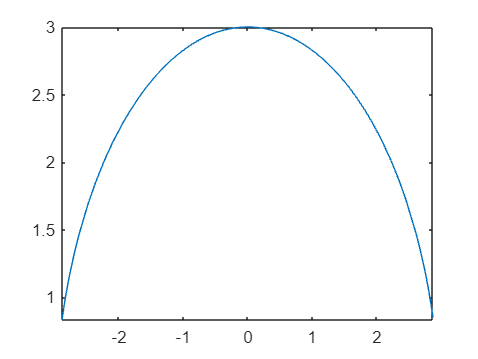

x0=3/2;
fplot(fun)

syms x
f(x)=fun(x)

$$f(x) = \sqrt{9-x^{2}}$$

f1(x)=diff(f)

$$f1(x) = -\frac{x}{\sqrt{9-x^{2}}}$$

f2(x)=diff(f1)

$$f2(x) = -\frac{x^{2}}{{\left(9-x^{2}\right)}^{3/2}}-\frac{1}{\sqrt{9-x^{2}}}$$

f3(x)=diff(f2)

$$f3(x) = -\frac{3\,x^{3}}{{\left(9-x^{2}\right)}^{5/2}}-\frac{3\,x}{{\left(9-x^{2}\right)}^{3/2}}$$

f1x0=double(f1(x0))

f1x0 =   -0.577350269189626

f2x0=double(f2(x0))

f2x0 =   -0.513200239279667

f3x0=double(f3(x0))

f3x0 =   -0.342133492853112

A teraz powtórz to dla funkcji wygenerowanej

[fun,x0]=gen3INFcw1(240661) % frazę <numer indeksu> trzeba zastąpić liczbą

fun = function_handle with value:
    @(x)exp(sqrt(x))

x0 =      4

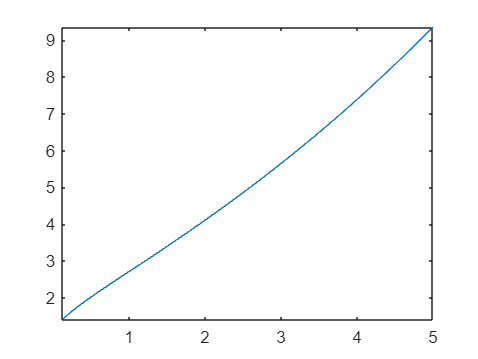

% Skopiuj kod z poprzedniej sekcji
fplot(fun)

syms x
f(x)=fun(x)

$$f(x) = {\mathrm{e}}^{\sqrt{x}}$$

f1(x)=diff(f)

$$f1(x) = \frac{{\mathrm{e}}^{\sqrt{x}}}{2\,\sqrt{x}}$$

f2(x)=diff(f1)

$$f2(x) = \frac{{\mathrm{e}}^{\sqrt{x}}}{4\,x}-\frac{{\mathrm{e}}^{\sqrt{x}}}{4\,x^{3/2}}$$

f3(x)=diff(f2)

$$f3(x) = \frac{{\mathrm{e}}^{\sqrt{x}}}{8\,x^{3/2}}-\frac{3\,{\mathrm{e}}^{\sqrt{x}}}{8\,x^{2}}+\frac{3\,{\mathrm{e}}^{\sqrt{x}}}{8\,x^{5/2}}$$

f1x0=double(f1(x0))

f1x0 =    1.847264024732663

f2x0=double(f2(x0))

f2x0 =    0.230908003091583

f3x0=double(f3(x0))

f3x0 =    0.028863500386448

Obliczenia dla ilorazu różnicowego z różnicą progresywną

h0=0.5; % Początkowa długość kroku różniczkowania
H=h0*(2.^(0:-1:-50)) % Generacja wektora z malejącymi długościami kroku do 2^(-50) 

H =    0.500000000000000   0.250000000000000   0.125000000000000   0.062500000000000   0.031250000000000   0.015625000000000   0.007812500000000   0.003906250000000   0.001953125000000   0.000976562500000   0.000488281250000   0.000244140625000   0.000122070312500   0.000061035156250   0.000030517578125   0.000015258789062   0.000007629394531   0.000003814697266   0.000001907348633   0.000000953674316   0.000000476837158   0.000000238418579   0.000000119209290   0.000000059604645   0.000000029802322   0.000000014901161   0.000000007450581   0.000000003725290   0.000000001862645   0.000000000931323   0.000000000465661   0.000000000232831   0.000000000116415   0.000000000058208   0.000000000029104   0.000000000014552   0.000000000007276   0.000000000003638   0.000000000001819   0.000000000000909   0.000000000000455   0.000000000000227   0.000000000000114   0.000000000000057   0.000000000000028   0.000000000000014   0.000000000000007   0.000000000000004   0.000000000000002   0.00000000000

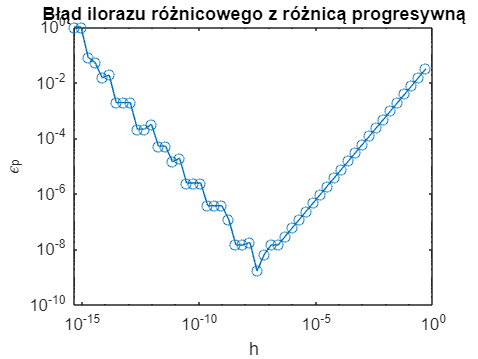

Dp= (fun(x0+H)-fun(x0))./H; % Obliczenie ilorazu różnicowego z różnicą progresywną dla wszystkich długości kroku z wektora H
erp= abs((Dp-f1x0)/f1x0); % Obliczenie modułu błędu względnego
loglog(H,erp,'o-') % Wykres w skali logarytmicznej
xlabel('h');ylabel('\epsilon_p');title('Błąd ilorazu różnicowego z różnicą progresywną')

Obliczenia dla ilorazu różnicowego z różnicą centralną

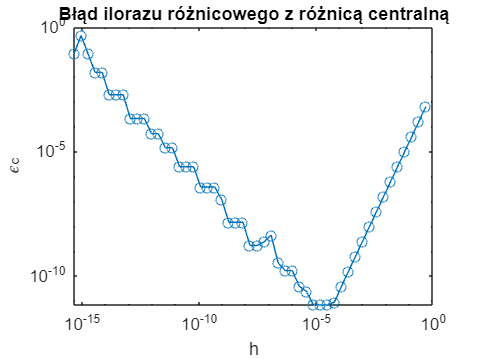

Dc=(fun(x0+H)-fun(x0-H))./(2*H) ; % Obliczenie ilorazu różnicowego z różnicą centralną dla wszystkich długości kroku z wektora H
erc = abs((Dc-f1x0)/f1x0); % Obliczenie modułu błędu względnego
loglog(H,erc,'o-') % Wykres w skali logarytmicznej
xlabel('h');ylabel('\epsilon_c');title('Błąd ilorazu różnicowego z różnicą centralną')

Porównanie: Rysujemy te same wykresy co w poprzednich dwóch sekcjach i dodajemy linie, które odpowiadają przybliżonej zależności między krokiem różniczkowania i błędem obcięcia. Jak wiadomo dla błąd obcięcia dla zwykłego (progresywnego) ilorazu różnicowego wynosi $\varepsilon_{obc}\approx\frac{f''(x_0)}{2 f'(x_0)} h$, natomiast dla ilorazu różnicowego z różnicą centralną $\varepsilon_{obc}\approx\frac{f'''(x_0)}{6 f'(x_0)}h^2$

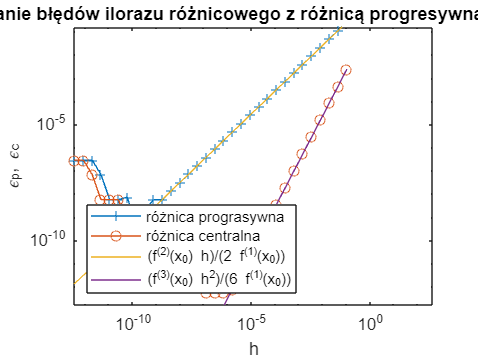

loglog(H,erp,'+-',H,erc,'o-',H,abs(f2x0/f1x0)*H/2,'-',H,abs(f3x0/f1x0)*H.^2/6,'-')
legend('różnica prograsywna','różnica centralna','(f^{(2)}(x_0) h)/(2 f^{(1)}(x_0))','(f^{(3)}(x_0) h^2)/(6 f^{(1)}(x_0))','Location','southwest')
xlabel('h');ylabel('\epsilon_p, \epsilon_c');title('Porównanie błędów ilorazu różnicowego z różnicą progresywną i centralną')

ylim([1e-12 1.000])

xlim([0 446])

Porównanie obliczeń z podwójną i pojedynczą precyzją

Hs=single(H); % Konwersja długości kroku do pojedynczej precyzji
x0s=single(x0); % Konwersja punktu różniczkowania
f1x0s=single(f1(x0s))

f1x0s = single
   1.8472641

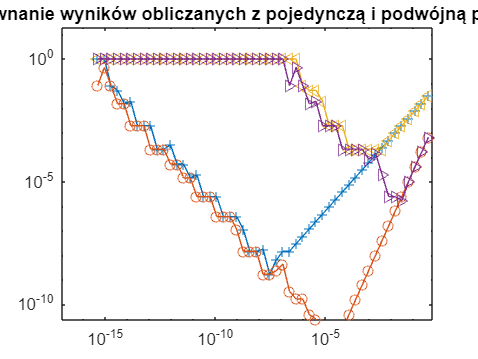


Dps=(fun(x0s+Hs)-fun(x0s))./Hs; % Powtórzenie obliczeń z różnicą progresywną w pojedynczej precyzji
erps= abs((Dps-f1x0s)/f1x0s); % Obliczenie modułu błędu względnego dla obliczeń z pojedynczą precyzją

Dcs=(fun(x0s+Hs)-fun(x0s-Hs))./(2*Hs) ; % Obliczenie ilorazu różnicowego z różnicą centralną dla wszystkich długości kroku z wektora H
ercs=abs((Dcs-f1x0s)/f1x0s);

loglog(H,erp,'+-',H,erc,'o-',Hs,erps,'<-',Hs,ercs,'>-')
title('Porównanie wyników obliczanych z pojedynczą i podwójną precyzją')

### Obserwacje

### Uwagi i wnioski

### Część 3. Zastosowanie ekstrapolacji Richardsona

Wyniki różniczkowania numerycznego można poprawiać stosując ekstrapolację Richardsona. Zapoznaj się ze składnią wywołania funkcji `ekstrap` i spróbuj poprawić wyniki uzyskane w poprzednich sekcjach przy użyciu obliczeń z podwójną precyzją. Spróbuj ekstrapolacji w odniesieniu zarówno dla różnicy centralnej, jak i różnicy progresywnej - pamiętaj jedynie o dopasowaniu wektora informującego program o wykładnikach w rozwinięciu asymptotycznym błędu do zagadnienia.

function y = pval1(p, x)
n=length(p)-1; % Odczytanie stopnia wielomianu
tmp=zeros(size(x)); % Zainicjowanie zmiennej do sumowania
for k=1:n+1
    tmp = tmp + p(k) * x.^(n-k+1); % Aktualizacja pomocniczej zmiennej sumacyjnej
end
y=tmp;
end

function y = pval2(p, x)
n=length(p)-1; % Odczytanie stopnia wielomianu
pow = ones(size(x)); % zainicjowanie zmiennej w której będę przechowywane kolejne potęgi (odpowiada potędze zerowej)
tmp = p(end)*pow; % Zainicjowanie zmiennej sumacyjnej
for k=1:n
    pow = pow .* x; % Obliczenie kolejnej potęgi
    tmp = tmp + p(end-k)*pow; % Aktualizacja zmiennej sumacyjnej
end
y=tmp;
end

function y = horner(p, x)
n=length(p)-1; % Odczytanie stopnia wielomianu
tmp = p(1);  % zaincjowanie zmiennej pomocniczej odpowiadającej zawartości najbardziej wewnętrznego nawiasu
for k=2:n+1
    tmp = tmp .* x + p(k); % Aktualizacja zmiennej pomocniczej tak by odpowiadała kolejnemu bardziej zewnętrznemu nawiasowi
end
y = tmp;
end